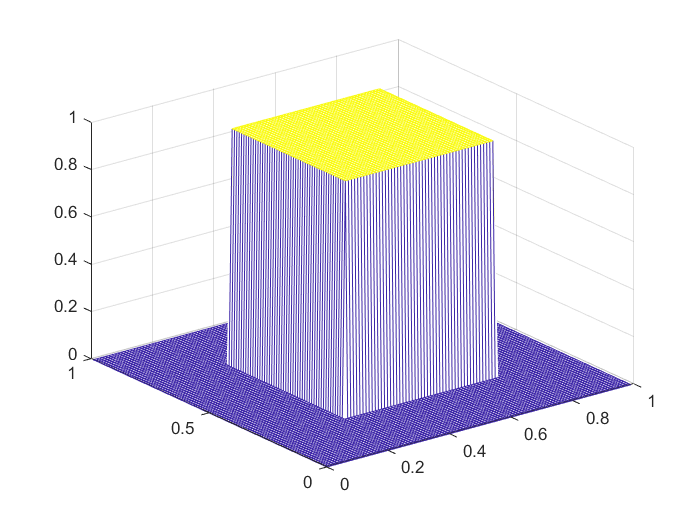

clear
[X,Y] = meshgrid(0:0.01:1-0.01);
Z = X>0.25 & X<0.75 & Y>0.25 & Y<0.75;
mesh(X,Y,Z)

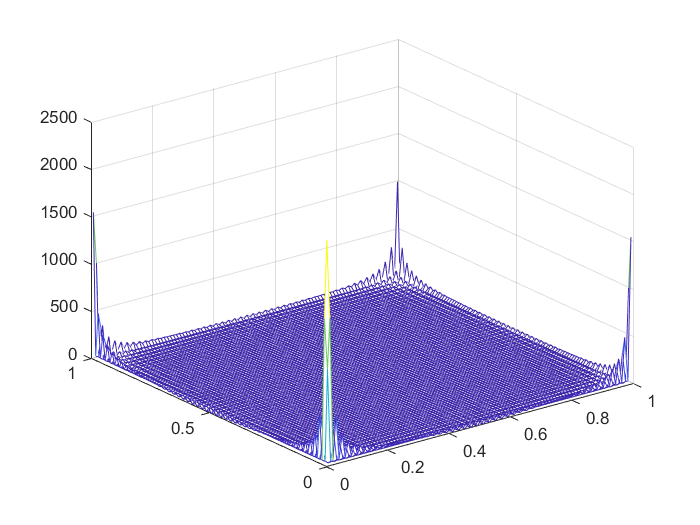

FFT = fft2(Z);
% FFT = fftshift(FFT);
mesh(X,Y,abs(FFT));

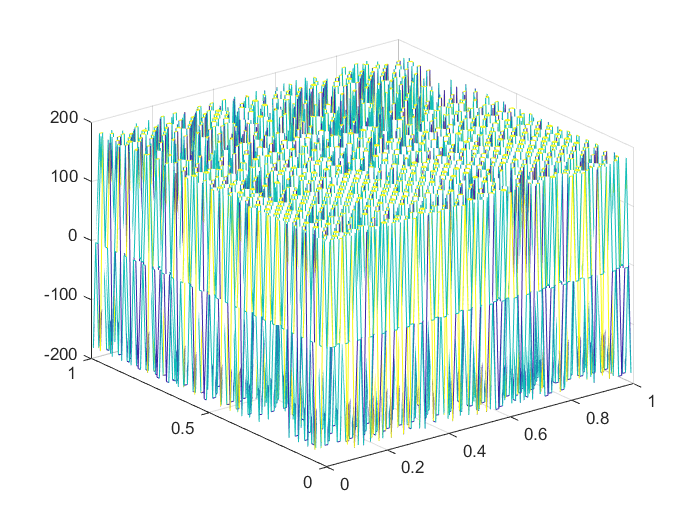

mesh(X,Y,angle(FFT)*180/pi)

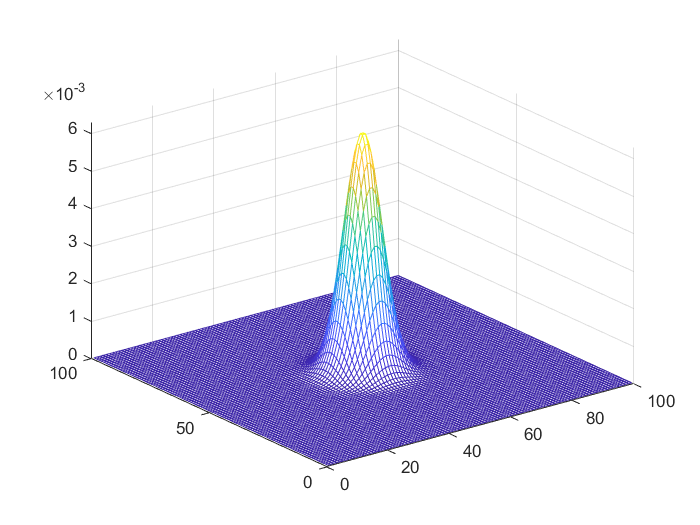

clear
[X,Y] = meshgrid(0:0.01:1-0.01);
Z = fspecial('gaussian',100,5); %size=100*100,sigma=5
mesh(Z)

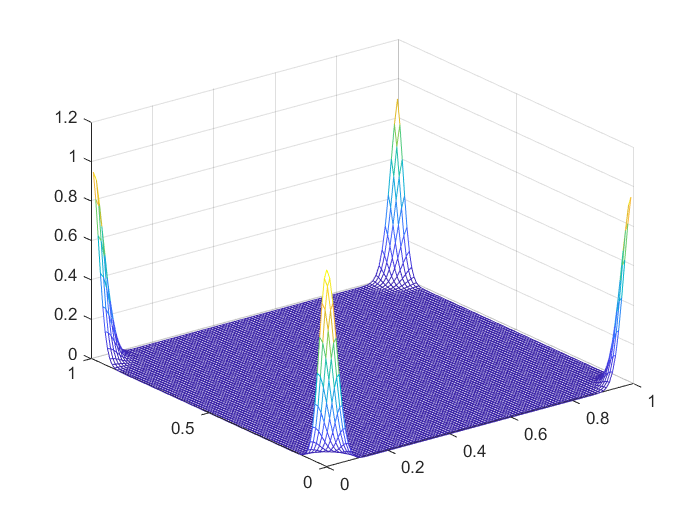

FFT = fft2(Z);
% FFT = fftshift(FFT);
mesh(X,Y,abs(FFT));

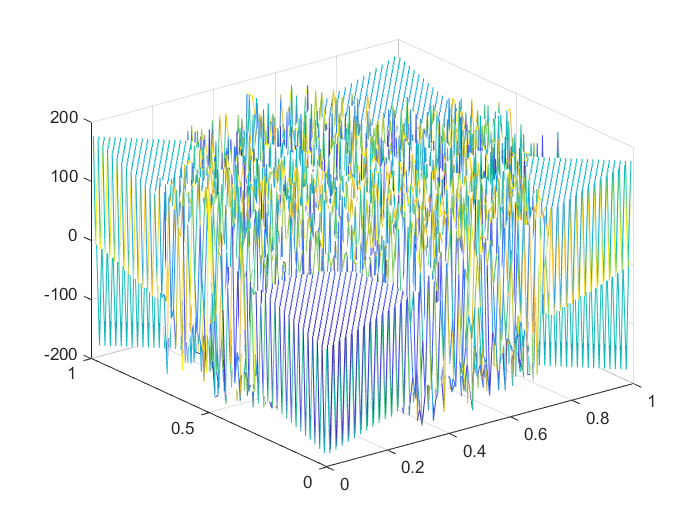

mesh(X,Y,angle(FFT)*180/pi)